The below code is ran once, the images in the folder Images are grayscale with three channels. All three being the same grayscale image. This step is necessary so the images are of the correct shape for an alexnet.

% rootdir = 'D:\units\computer vision and pattern recognition\Computer_Vision_Project\Images';
% srcFiles = dir(fullfile(rootdir,'**\*.jpg'));
% filelist = srcFiles(~[srcFiles.isdir]);
% for k = 1:numel(filelist)
%     filename = fullfile(filelist(k).folder,filelist(k).name);
%     I = imread(filename);
%     [rows, columns, numberOfColorChannels] = size(I);
%     if numberOfColorChannels == 1
%         newImage = cat(3, I, I, I); 
%         imwrite(newImage, filename)
%     end
% end

3. Use transfer learning based on a pre-trained network, for instance AlexNet [Krizhevsky et al., 2012], in the following two manners (in both of the cases you should get an accuracy above 85%)

4. Optionally, in tasks 2 and 3, you could improve data augmentation, adding to the left-right reflection a random cropping of a sufficiently large region, followed by small rotations and rescaling (an example of crop and rescaling is shown in Fig. 3);  *Note: the images are transformed, but the net doesn't accept a transformedDatastore*

6. optionally, in task 3, you could employ nonlinear SVMs; *Note: ecoc is used with polynomial kernel*

%clear all

trainDatasetPath = fullfile('Images','train');
testDatasetPath = fullfile('Images','test');

imdsInit = imageDatastore(trainDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore(testDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

labelCount = countEachLabel(imdsInit)

labelCount = 15×2 table
       Label        Count
    ____________    _____

    Bedroom          100 
    Coast            100 
    Forest           100 
    Highway          100 
    Industrial       100 
    InsideCity       100 
    Kitchen          100 
    LivingRoom       100 
    Mountain         100 
    Office           100 
    OpenCountry      100 
    Store            100 
    Street           100 
    Suburb           100 
    TallBuilding     100 


% split in training and validation sets: 85% - 15%
quotaForEachLabel=0.85;
[imdsTrain,imdsValidation] = splitEachLabel(imdsInit,quotaForEachLabel,'randomize');

net = alexnet

net =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


net.Layers

ans =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0

imageSize = net.Layers(1).InputSize

imageSize =    227   227     3


% Alexnet requires 224x224x3 images, but some of the images in the
% datastore have just one channel

% see beginning for solution

augSelected = "RandXReflection" % task 4. is additional data augmentation

augSelected = "RandXReflection"

rows = 200

columns = 257

numberOfColorChannels = 3

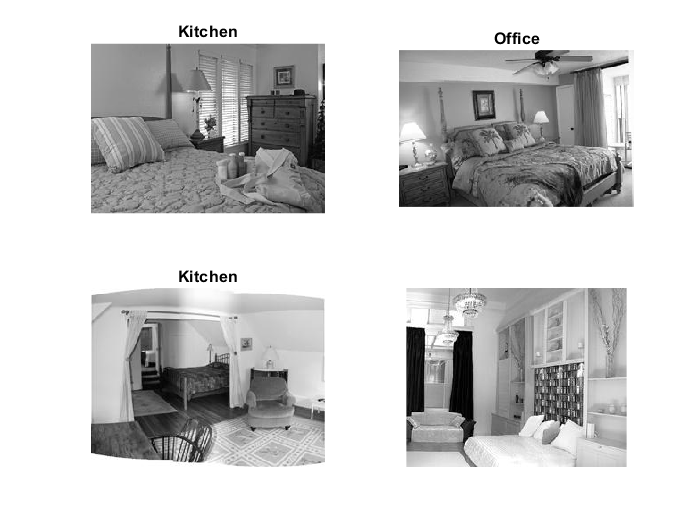

rows = 200

columns = 246

numberOfColorChannels = 3


if augSelected == 'plus cropping'
    auimdsTrain = transform(imdsTrain, @plusAugPipeline, IncludeInfo=true);    
else
    aug = imageDataAugmenter('RandXReflection',1);
    auimdsTrain = augmentedImageDatastore(imageSize,imdsTrain,'DataAugmentation',aug);
end

auimdsValidation = augmentedImageDatastore(imageSize,imdsValidation);
auimdsTest = augmentedImageDatastore(imageSize,imdsTest);

for i = 2:3
    img = readimage(imdsTrain,i); % TODO why augmented image ds is not working here
    imshow(img)
    [rows, columns, numberOfColorChannels] = size(img)
end


YTrain = imdsTrain.Labels;
YValidation = imdsValidation.Labels;
YTest = imdsTest.Labels;

3A/4. Freeze the weights of all the layers but the last fully connected layer and fine-tune the weights of the last layer based on the same train and validation sets employed before;  *Note: reached accuracy, net and data saved in forTransferA.mat*

layersTransfer = net.Layers(1:end-3);

layers = [
    layersTransfer
    fullyConnectedLayer(height(labelCount),'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',auimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

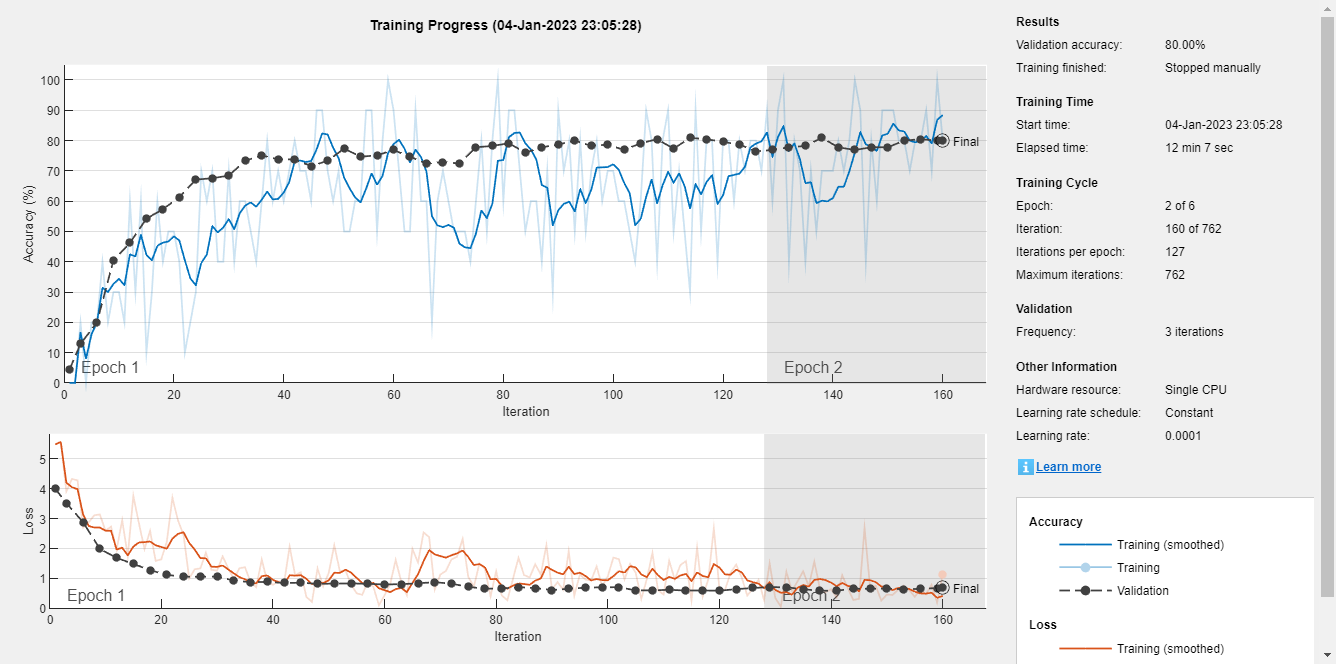

netTransfer = trainNetwork(auimdsTrain,layers,options);

[YPred,scores] = classify(netTransfer,auimdsTest);
accuracy = mean(YPred == YTest)

accuracy = 0.8054

3B/4/6. Employ the pre-trained network as a feature extractor, accessing the activation of an intermediate layer (for instance the last convolutional layer) and train a multiclass linear SVM. For implementing the multiclass SVM use any of the approaches seen in the lectures, for instance DAG  *Note: Linear ecoc is used with svm as Learner, not DAG*

*DAG try: https://it.mathworks.com/matlabcentral/fileexchange/65232-binary-and-multi-class-svm*

selectedSVM= "linSVM" % task 6. is non linear svm

selectedSVM = "linSVM"

featureLayer = 'conv5'

featureLayer = 'conv5'

featuresTrain = activations(net, auimdsTrain, featureLayer, 'OutputAs', 'rows');
featuresValidation = activations(net, auimdsValidation, featureLayer, 'OutputAs', 'rows');
featuresTest = activations(net, auimdsTest, featureLayer, 'OutputAs', 'rows');

if selectedSVM == 'linSVM'
    t = templateLinear('Learner', 'svm', 'Regularization', 'lasso');
else
    t = templateSVM('Standardize',true,'KernelFunction','polynomial'); % 6. optionally, in task 3, you could employ nonlinear SVMs;;
end

PMdl = fitcecoc(featuresTrain,YTrain,'Learners',t,'FitPosterior',true,...
    'Verbose',2, 'OptimizeHyperparameters','auto');
Mdl = PMdl.BinaryLearners{1};           % Extract trained, compact classifier

load('forTransferLinSVMB.mat')
YPred = predict(PMdl,featuresValidation);

table(YValidation,YPred,...
    'VariableNames',{'TrueLabels','PredictedLabels'})

ans = 225×2 table
    TrueLabels    PredictedLabels
    __________    _______________

     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Office     
     Bedroom          Office     
     Bedroom          Kitchen    
     Bedroom          Highway    
     Bedroom          Office     
     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Coast      
     Bedroom          Kitchen    
     Coast            Coast      


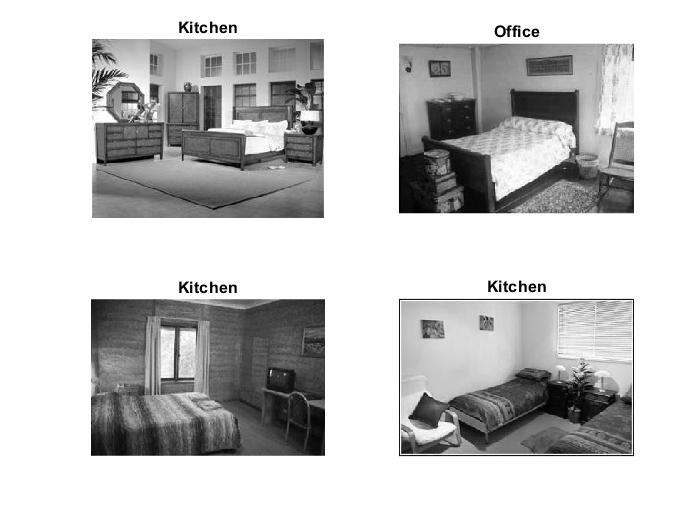


idx = [1 5 10 15];
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    label = YPred(idx(i));
    
    imshow(I)
    title(label)
end


accuracy = mean(YPred == YValidation) % TODO bad accuracy needs fixing

accuracy = 0.4000

YPred = predict(PMdl,featuresTest);

table(YTest,YPred,...
    'VariableNames',{'TrueLabels','PredictedLabels'})

ans = 2985×2 table
    TrueLabels    PredictedLabels
    __________    _______________

     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Office     
     Bedroom          Kitchen    
     Bedroom          Office     
     Bedroom          Kitchen    
     Bedroom          Highway    
     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Kitchen    
     Bedroom          Office     
     Bedroom          Kitchen    
     Bedroom          Office     
     Bedroom          Kitchen    
     Bedroom          Office     
     Bedroom          Office     


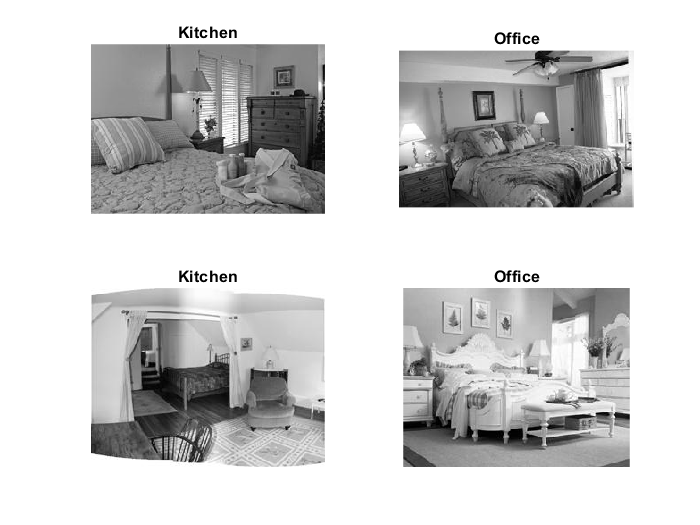


idx = [1 5 10 15];
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    label = YPred(idx(i));
    
    imshow(I)
    title(label)
end


accuracy = mean(YPred == YTest)

accuracy = 0.3896

function [dataOut,info] = plusAugPipeline(dataIn,info)

dataOut = cell([size(dataIn,1),2]);

for idx = 1:size(dataIn,1)
    temp = dataIn{idx};
    
    temp = imresize(temp,[227,227,3]);
    
    win = randomWindow2d([227,227,3], [180 180]);
    temp  = imcrop(temp, win);
    temp = augmentedImageDatastore([227,227,3], temp);
    %TODO small rotation and rescaling too
    
    % Form second column expected by trainNetwork which is the expected response,
    % the categorical label in this case
    dataOut(idx,:) = {temp,info.Label(idx)};
end

end